Considera el problema:


$$\left\{\begin{array}{l}-u''-u=0,\\ u(0) = 3, \\ u(\frac{\pi}{2}) = 7.\end{array}\right.$$


La resolución por dos métodos distintos es como sigue:

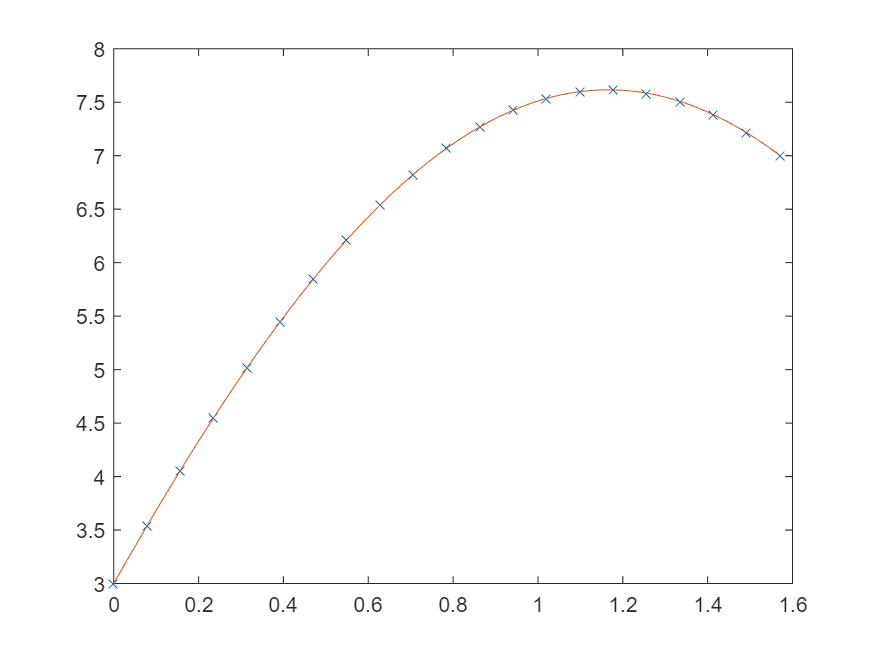

clf

% Método a comparar con elementos finitos
m = 1;
F = struct('u', @(x) zeros(size(x)), ...
            'v', @(x)  -1.*ones(size(x)), ...
            'w', @(x) zeros(size(x)), ...
            'm', m);
bc = struct('blk_a', true, 'a', 0,    'ya', 3,  'ha', 1, ...
            'blk_b', true, 'b', pi/2, 'yb', 7 , 'hb', 1);

%h = 0.1
n = round(bc.b-bc.a)/0.1;
nl = struct('yk', ones(1,n+1), 'maxit', 400, 'tol', 1.e-6);
[x1, y1, k1] = dfif(F, bc, n, nl);

plot(x1,y1,'x'); hold on


clear sd %borra componentes adicionales (futuras) al volver a este ejercicio

% Elementos finitos
sd(1) = struct('a', 0, 'b', pi/2, 'n', 150, 'nsd', 1);
%malla
m = mesher(sd, 2);
%condiciones de contorno
bc = struct('a', sd(  1).a, 'ua', 3, ...
            'b', sd(end).b, 'ub', 7);
%EDO
F = struct('p', @(x, nsd)  1, ...
           'q', @(x, nsd)  0, ...
           'r', @(x, nsd) -1, ...
           'f', @(x, nsd)  0);
%formulas de cuadratura
qd = qd_formula;
%solucion aproximada
uh = ef(F, m, bc, qd.gauss2p);
plot(m.xn,uh)

function qd = qd_formula
%QD_FORMULA   Estructura para formulas de cuadratura
x1 = 0.339981043584856; w1 = 0.652145154862546;
x2 = 0.861136311594953; w2 = 0.347854845137454;
qd = struct('poncelet', struct('n', 1, 'w', [1],       'x', [0.5]), ...
            'trapecio', struct('n', 2, 'w', [0.5 0.5], 'x', [0 1]), ...
            'gauss2p',  struct('n', 2, 'w', [0.5 0.5], 'x', [(1-sqrt(1/3))/2 (1+sqrt(1/3))/2]), ...
            'gauss4p',  struct('n', 4, 'w', [w2 w1 w1 w2]/2, 'x', (1 + [-x2 -x1 x1 x2])/2)); %#ok<NBRAK>
end

function m = mesher(sd, deg)
%MESHSER   Construccion de la malla de elementos finitos de grado M.DEG, 
%    con M.NEL elementos, M.NVER vertices de coordenadas M.XV, 
%    con M.NNOD nodos de coordenadas M.XN y numero de subdominio M.NSD
m.xv = [sd(1).a]; m.xn = m.xv; m.nsd = [];
for i = 1:length(sd)
  h     = (sd(i).b-sd(i).a)/sd(i).n;
  m.xv  = [m.xv,  sd(i).a + h*(1:sd(i).n)];
  m.xn  = [m.xn,  sd(i).a + h*(1:sd(i).n*deg)/deg];
  m.nsd = [m.nsd, sd(i).nsd*ones(1,sd(i).n)];
end
m.nver = length(m.xv);
m.nnod = length(m.xn);
m.nel  = length(m.nsd);
m.deg  = deg;
end